# Matlab quick look

Matlab is very similar to R.  Matlab is often used in engineering and may be used for deep learning and maching learning.  It is also often used for signal process, image analysis, and is common for medical research.

## Syntax

### **Comments**

%comments are started with a %
%{
    If you have a lot of comments you may wish to use this syntax.
    It is known as a block comment.  Anything between the "%{" 
    and "%}" will not affect our code.
%}

% There is a keyboard shortcut (cmd+/ or ctrl+/) to automattically comment
% out a line. 

### **Variables**

%Variables are assigned using the = sign.
x = 6 % assigns the value 6 to the variable x

x = 6

y = 7 % assigns the value 7 to the variable 7

y = 7


x*y % prints the resutls of x*y

ans = 42


% If you do not wish to print the results add a ; to the end

x/y;  % this will not display anything because of the semicolon (;)


### **Navigation**

We can use the windows to the left to navigate our workspace or we can use commands.  The commands in Matlab are VERY simlar to those in a *nix enviroment.  If you are familiar with the terminal on either Linux, Unix, or Mac than this will be very similar.

% to get the current directory we type:
pwd

ans = '/MATLAB Drive'


% We can store that in a variable

cur_dir = pwd

cur_dir = '/MATLAB Drive'


% We can create a directory with:

% mkdir carData  

% This creates a directory named 'carData' if you look to the left you
% should see the directory there.

% The command 'cd' is used to change directory. 

% cd carData/

% We can move back to the previous directory in one of two ways.  We can
% either use the variable we saved before or we can use the shortcut '..'
%
% The two dots are a shortcut pointing to the directory 'above' the current
% one.  A little bit of "Ender's Game" here making us put spacial reasoning
% into our folder structure.

% Uncomment one of the following to move back to the parent directory

% cd ..

% cd(cur_dir)

**Reading in Data**

filename = "https://raw.githubusercontent.com/dclinkenbeard/summer-intro-to-coding-2022/main/SuperHero.csv"

filename = "https://raw.githubusercontent.com/dclinkenbeard/summer-intro-to-coding-2022/main/SuperHero.csv"

supers = readtable(filename)

supers = 20×11 table
           Name           Universe    Eye_Color     Height    Intelligence    Strength    Speed    Durability    Power    Combat    Tier
    __________________    ________    __________    ______    ____________    ________    _____    __________    _____    ______    ____

    {'Batman'        }    {'DC' }     {'Blue'  }      188          90            25         17         15          25      100       1  
    {'The Joker'     }    {'DC' }     {'Green' }    195.6          85             1          8         12          15       45       1  
    {'Oracle'        }    {'DC' }     {'Blue'  }    177.


summary(supers)

Variables:

    Name: 20×1 cell array of character vectors

    Universe: 20×1 cell array of character vectors

    Eye_Color: 20×1 cell array of character vectors

    Height: 20×1 double

        Values:

            Min          160  
            Median     177.9  
            Max        248.9  

    Intelligence: 20×1 double

        Values:

            Min          60   
            Median       75   
            Max          95   

    Strength: 20×1 double

        Values:

            Min           1   
            Median       25   
            Max         100   

    Speed: 20×1 double

        Values:

            Min           1   
            Median       25   
            Max         100   

    Durability: 20×1 double

        Values:

            Min            5  
            Median      17.5  
            Max          100  

    


% We can access individual columns with 'dot notation' as seen here

supers.Eye_Color

ans = 20×1 cell array
    {'Blue'  }
    {'Green' }
    {'Blue'  }
    {'Blue'  }
    {'Brown' }
    {'Blue'  }
    {'Green' }
    {'Blue'  }
    {'Blue'  }
    {'Blue'  }
    {'Brown' }
    {'Blue'  }
    {'Yellow'}
    {'Red'   }
    {'Green' }
    {'Blue'  }
    {'Green' }
    {'Grey'  }
    {'Brown' }
    {'Brown' }



mean(supers.Height)

ans = 181.7300

median(supers.Height)

ans = 177.9000

mode(supers.Height)

ans = 167.6000

min(supers.Height)

ans = 160

max(supers.Height)

ans = 248.9000

**Basic Plots**

Basic plotting is very simple in Matlab. 

More detail here: [https://www.mathworks.com/help/matlab/ref/plot.html](https://www.mathworks.com/help/matlab/ref/plot.html)

#### Line plots

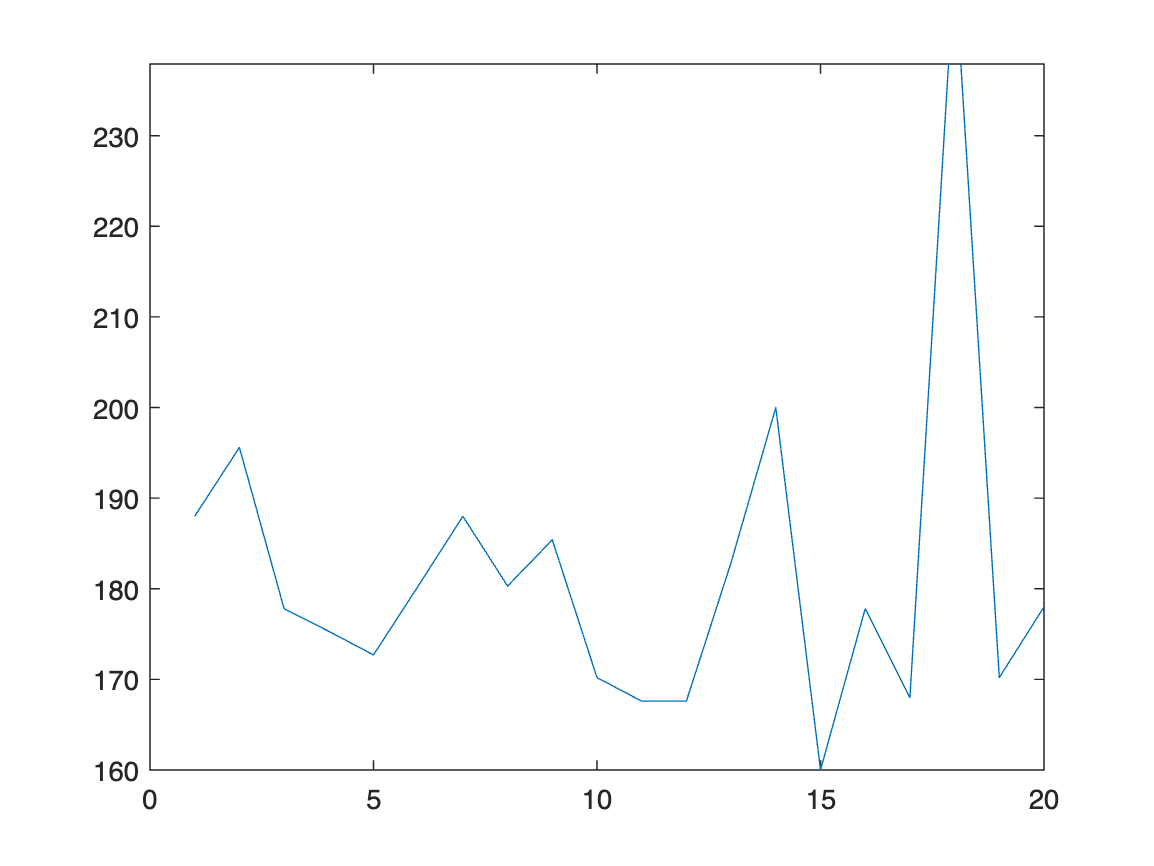

% this will create a basic line plot
plot(supers.Height)

Counting / plotting categorical data

% we can get a summary of our categorical data using groupsummary()

category_counts = groupsummary(supers,"Eye_Color")

category_counts = 6×2 table
    Eye_Color     GroupCount
    __________    __________

    {'Blue'  }        9     
    {'Brown' }        4     
    {'Green' }        4     
    {'Grey'  }        1     
    {'Red'   }        1     
    {'Yellow'}        1     



% To display the data we will use histogram()
% first we need to ensure our data is categorical.

supers.Eye_Color = categorical(supers.Eye_Color)

supers = 20×11 table
           Name           Universe    Eye_Color    Height    Intelligence    Strength    Speed    Durability    Power    Combat    Tier
    __________________    ________    _________    ______    ____________    ________    _____    __________    _____    ______    ____

    {'Batman'        }    {'DC' }      Blue          188          90            25         17         15          25      100       1  
    {'The Joker'     }    {'DC' }      Green       195.6          85             1          8         12          15       45       1  
    {'Oracle'        }    {'DC' }      Blue        177.8    

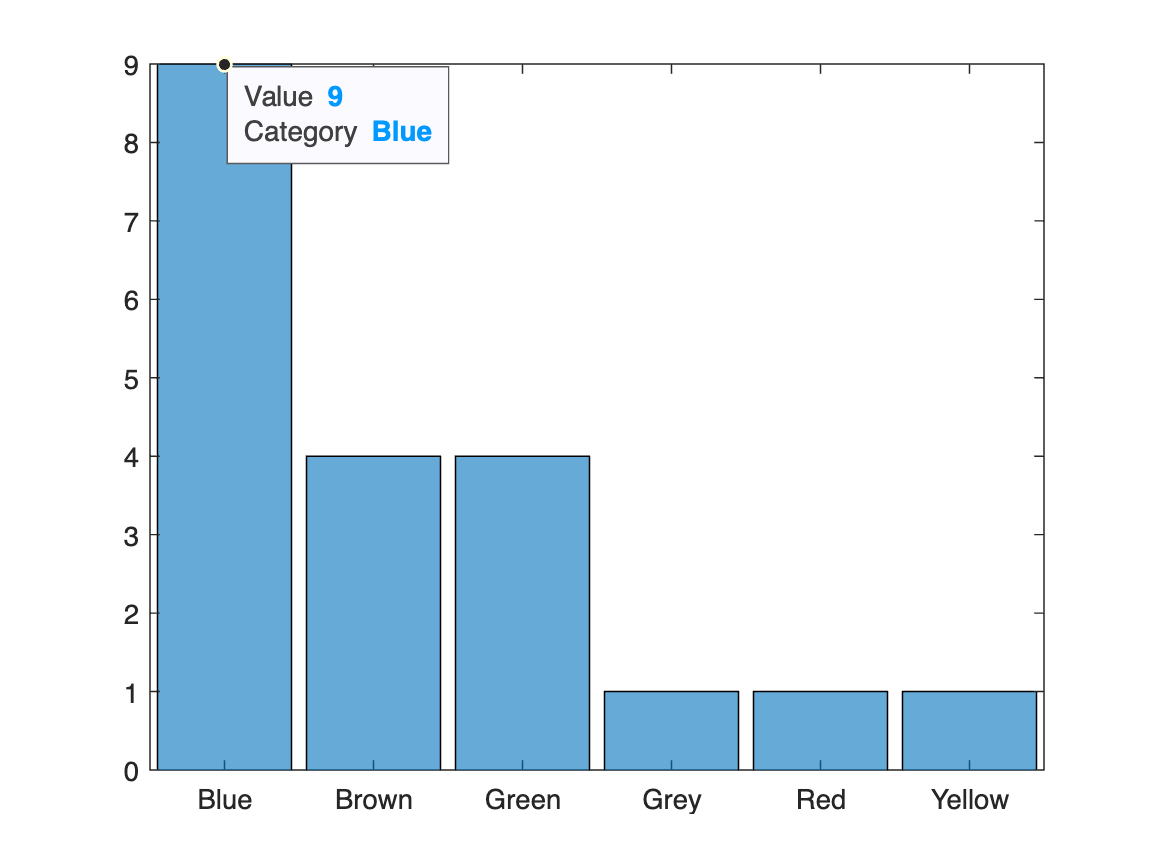



histogram(supers.Eye_Color)

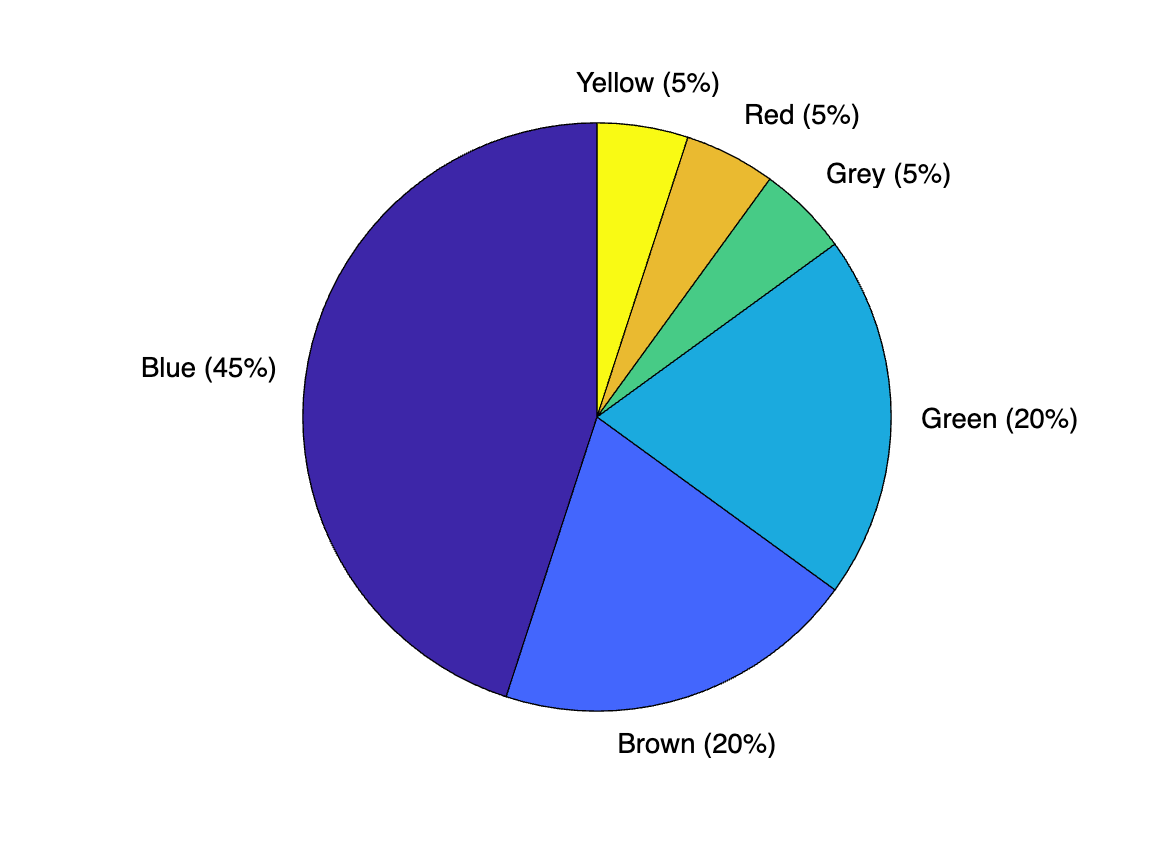


% pie charts are easy too

pie(supers.Eye_Color)

## Built in Datasets

Matlab has several [built in](https://www.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html) datasets.  We can access these using the 'load' command.

[https://www.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html](https://www.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html)

The following is thanks to: [https://www.youtube.com/watch?v=3dvAzozBmJk](https://www.youtube.com/watch?v=3dvAzozBmJk)

Unfortunatly all of the values are stored in single column arrays.  We can combine them into a single table however.

% First we can clear our workspace (this is optional but for demonstration
% purposes this makes things a lot easier).
%
% Right click on the workspace and select 'Clear Workspace' 

load carbig.mat

% Note the ... below are to allow the command to be split across multiple
% lines.

carTable = table(Acceleration,cyl4,Cylinders,...
    Displacement,Horsepower,Mfg,...
    Model,Model_Year,MPG,...
    org,Origin,Weight,when)

carTable = 406×13 table
    Acceleration    cyl4     Cylinders    Displacement    Horsepower         Mfg                        Model                    Model_Year    MPG      org      Origin     Weight    when 
    ____________    _____    _________    ____________    __________    _____________    ____________________________________    __________    ___    _______    _______    ______    _____

          12        Other        8            307            130        chevrolet        chevrolet chevelle malibu                   70         18    USA    

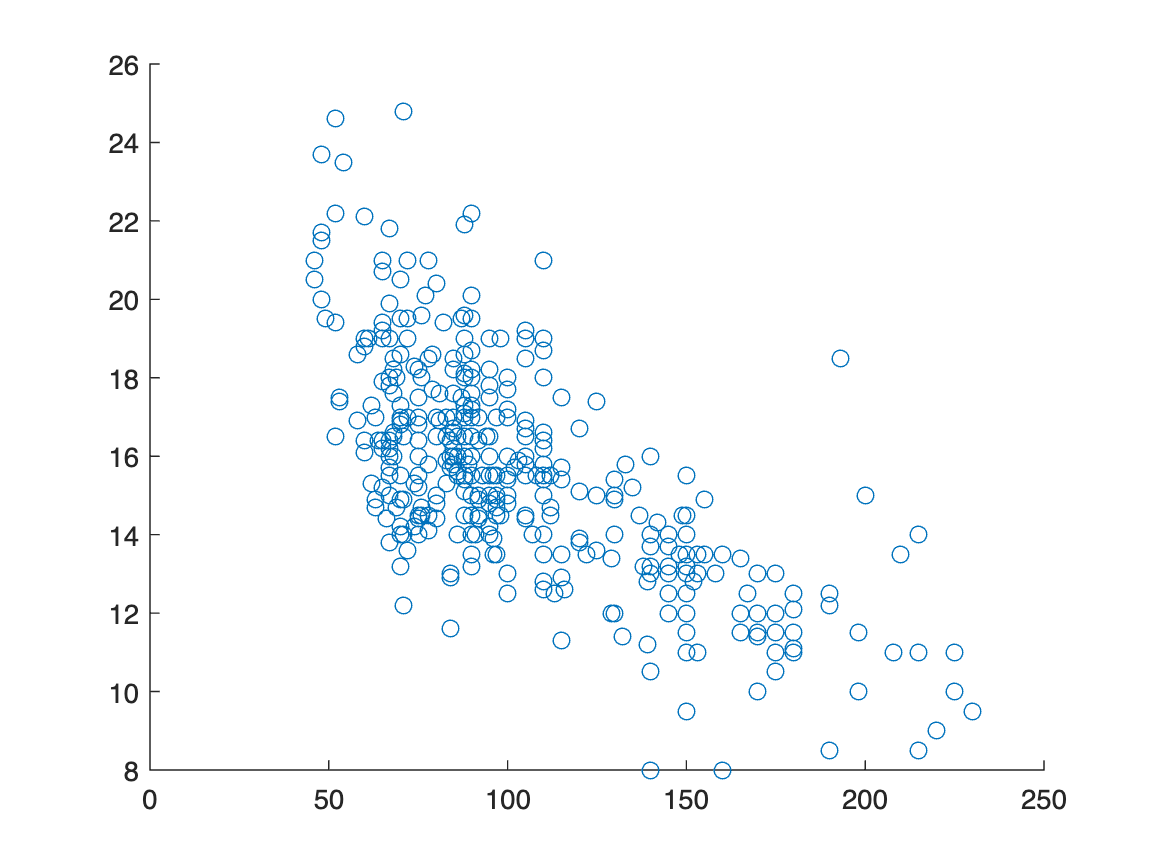

ans = -30


scatter(carTable.Horsepower,carTable.Acceleration)

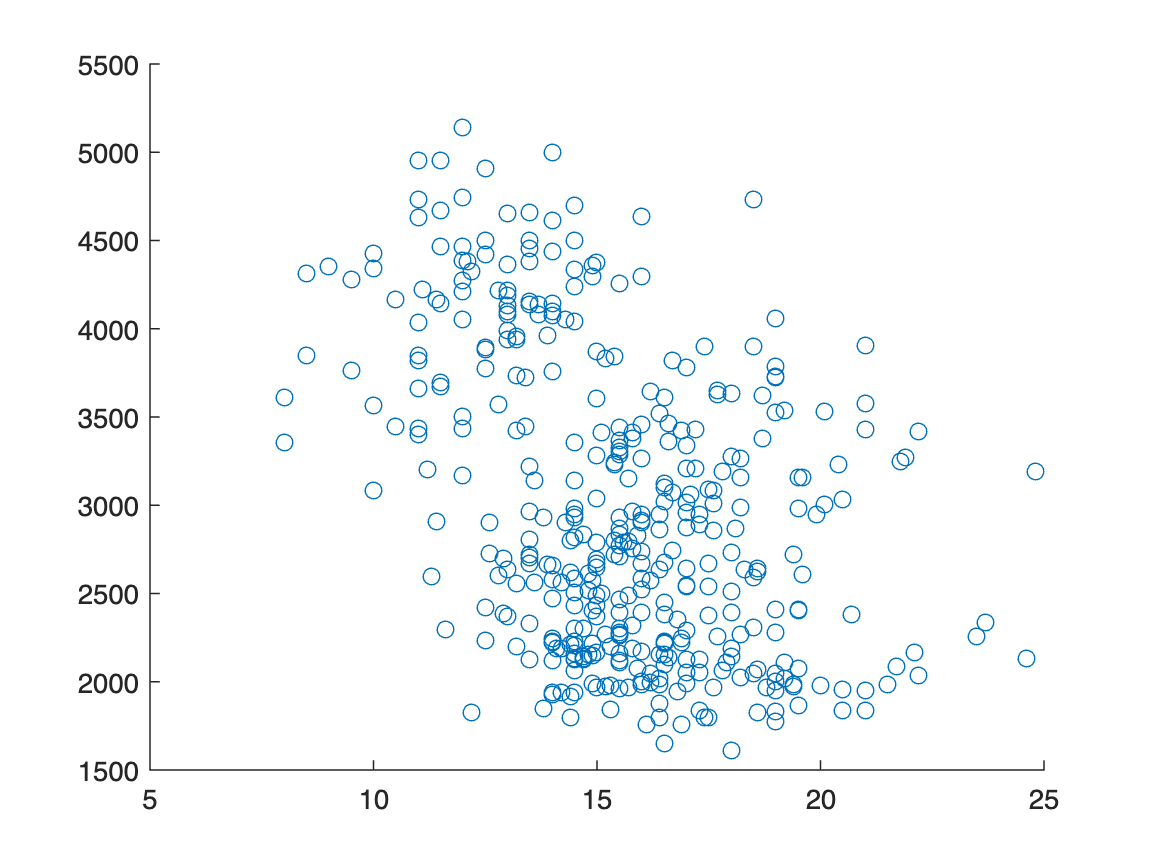

% If we click the table that was just generated we can manipulate it with
% built in tools.
% Notice this gives us options on top.  We can use these options to update
% our chart.

scatter(carTable.Acceleration, carTable.Weight)

### More complex plots

If we wish to add more to a plot that is something else that Matlab lets us do.  For example if we would like to add a trendline to the prevous scatter plot we would do the folowing.  FIrst we need to generate a line to add to the chart.  We do that with the polyfit function.

p = polyfit(carTable.Acceleration,carTable.Weight,1)

p = 1.0e+03 *

   -0.1299    4.9961


Then we get the x coordinates of the smallest and largest points from our x axis variable and store it in a matrix

px = [min(carTable.Acceleration) max(carTable.Acceleration)]

px =     8.0000   24.8000


The next variable is  py.  This is a matrix that is generated by using polyval.  Polyval evaluates the equation we generated with polyfit at each of the points we stored in px.  The resulting matrix gives us the y values that correspond to the x values we found before.

py = polyval(p, px)

py = 1.0e+03 *

    3.9566    1.7735


Finally we need to plot all of this.  We will first generate a scatter plot and add in a parameter to fill in each points (because it looks nice).

Then we use the command 'hold' and set it to 'on'  this tells Matlab to hold the chart we created and draw the next chart on top. 

Finally we plot the line we generated with the steps above.

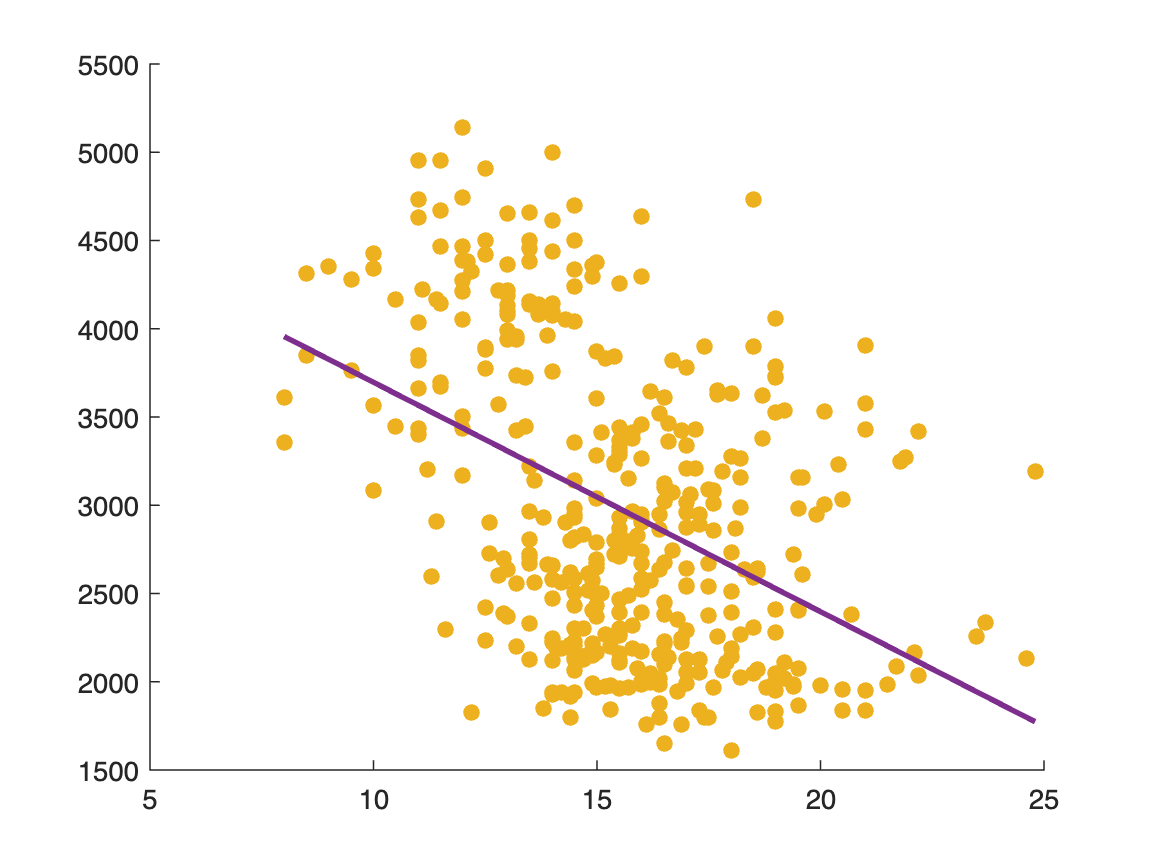

scatter(carTable.Acceleration, carTable.Weight, 'filled')
hold on % here we are telling Matlab to retain the previous (scatter) plot when we draw the next plot.
plot(px, py, 'LineWidth',2)

## WYSIWYG tables

Matlab looks for a Matrix called X when using the built in table generation.  We can see how this works below:

X = [MPG,Acceleration,Displacement,Weight,Horsepower]

X = 1.0e+03 *

    0.0180    0.0120    0.3070    3.5040    0.1300
    0.0150    0.0115    0.3500    3.6930    0.1650
    0.0180    0.0110    0.3180    3.4360    0.1500
    0.0160    0.0120    0.3040    3.4330    0.1500
    0.0170    0.0105    0.3020    3.4490    0.1400
    0.0150    0.0100    0.4290    4.3410    0.1980
    0.0140    0.0090    0.4540    4.3540    0.2200
    0.0140    0.0085    0.4400    4.3120    0.2150
    0.0140    0.0100    0.4550    4.4250    0.2250
    0.0150    0.0085    0.3900    3.8500    0.1900


varNames = {'MPG'; 'Acceleration'; 'Displacement'; 'Weight'; 'Horsepower'};
